### **Aplicação do Algoritmo Genético**

**Antes de rodar sempre adicionar a pasta "Scripts" ao path.**

INPUT.world.gravity = 9.81;  %(m/s²)
INPUT.world.density = 1.108; %(kg/m³)
INPUT.world.friction = 0.04;
INPUT.decisions.TO_dist = 55; %(m)
INPUT.decisions.obstacle = 0.8; %(m)
INPUT.decisions.friction_drag = 0.016;
INPUT.decisions.wing_density = 1.5;

GENETIC_PARAMETERS.cons = [0.200 0.500    % Corda na Raíz (m)
                           0.200 1.000    % Razão de Afilamento (%)
                           2.000 3.600    % Envergadura (m)
                           0.200 1.000    % Posição de Afilamento (%)
                           0.000 0.080    % Offset na Ponta
                           0.000 1.000    % Torção Intermediária (cat)
                           0.000 1.000    % Torção na Ponta (cat)
                           0.000 1.000    % Aerofólio (cat)                           
                           0.000 1.000];  % Grupo Motopropulsor (cat)

GENETIC_PARAMETERS.max_generations = 60;
GENETIC_PARAMETERS.pop_size = 20;
GENETIC_PARAMETERS.prob_crossover = 0.9;
GENETIC_PARAMETERS.prob_mutation = 0.15;
GENETIC_PARAMETERS.elitism_preservation = 1;

[GENETIC_OUTPUTS] = GA_ELITISM(INPUT, GENETIC_PARAMETERS);

 
  Athena Vortex Lattice  Program      Version  3.37 
  Copyright (C) 2002   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
   Quit    Exit program 
 
  .OPER    Compute operating-point run cases 
  .MODE    Eigenvalue analysis of run cases 
  .TIME    Time-domain calculations 
 
   LOAD f  Read configuration input file 
   MASS f  Read mass distribution file 
   CASE f  Read run case file 
 
   CINI    Clear and initialize run cases 
   MSET i  Apply mass file data to stored run case(s) 
 
  .PLOP    Plotting options 
   NAME s  Specify new configuration name 
 
 AVL   c>   
 Reading file: Astra.avl  ... 
 
 Configuration: Astra                                                        
 
   Building surface: Main W

### Plot do Gráfico das Gerações (Melhor Indivíduo e Média dos Indivíduos)

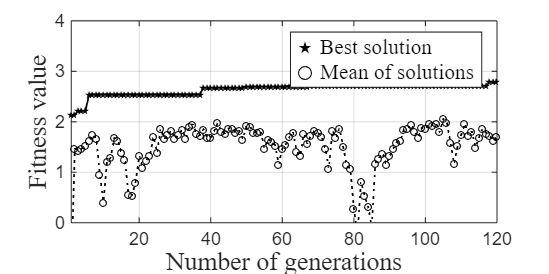

PLOT_EVOLUTION(GENETIC_PARAMETERS, GENETIC_OUTPUTS)

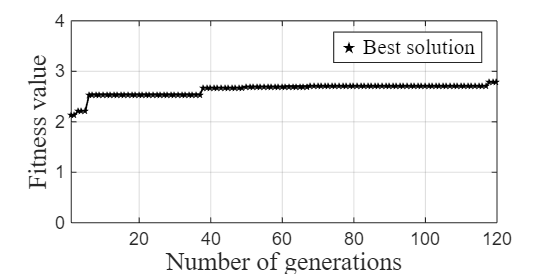


PLOT_EVOLUTION_BEST(GENETIC_PARAMETERS, GENETIC_OUTPUTS)

###  Tratamento dos Resultados

Ordem na qual os genes se apresentam por coluna: 1. Corda na Raíz, 2. Razão de Afilamento, 3. Envergadura, 4. Posição de Afilamento, 5. Offset na Ponta, 6. Torção Intermediária, 7. Torção na Ponta, 8. Aerofólio, 9. GMP, 10.Fitness, 11.MTOW, 12.invMTOW, 13.EW, 14.Sref, 15.AR.

% Elimina as soluções repetidas:
RESULTS.unique_solutions = unique(GENETIC_OUTPUTS.all_solutions(:,1:10), 'rows');

% Ordena as soluções de forma decrescente:
RESULTS.rank = RESULTS.unique_solutions(:,10);
[RESULTS.rank, RESULTS.sort_order] = sort(RESULTS.rank, 'descend');
RESULTS.ordered_solutions = RESULTS.unique_solutions(RESULTS.sort_order, :);

% Calcula o MTOW, EW, S_ref e AR das soluções únicas:
PARAMETER_OUTPUTS = MTOW_CALCULATION(INPUT, RESULTS)

 
  Athena Vortex Lattice  Program      Version  3.37 
  Copyright (C) 2002   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
   Quit    Exit program 
 
  .OPER    Compute operating-point run cases 
  .MODE    Eigenvalue analysis of run cases 
  .TIME    Time-domain calculations 
 
   LOAD f  Read configuration input file 
   MASS f  Read mass distribution file 
   CASE f  Read run case file 
 
   CINI    Clear and initialize run cases 
   MSET i  Apply mass file data to stored run case(s) 
 
  .PLOP    Plotting options 
   NAME s  Specify new configuration name 
 
 AVL   c>   
 Reading file: Astra.avl  ... 
 
 Configuration: Astra                                                        
 
   Building surface: Main W

PARAMETER_OUTPUTS = struct with fields:
       MTOW: [4497×1 double]
    invMTOW: [4497×1 double]
       Sref: [4497×1 double]
         EW: [4497×1 double]
         AR: [4497×1 double]



% Organiza tudo em uma solução final:
RESULTS.final_solution = [RESULTS.ordered_solutions PARAMETER_OUTPUTS.MTOW];
RESULTS.final_solution = [RESULTS.final_solution PARAMETER_OUTPUTS.invMTOW];
RESULTS.final_solution = [RESULTS.final_solution PARAMETER_OUTPUTS.EW];
RESULTS.final_solution = [RESULTS.final_solution PARAMETER_OUTPUTS.Sref];
RESULTS.final_solution = [RESULTS.final_solution PARAMETER_OUTPUTS.AR];

### Gráficos dos Resultados

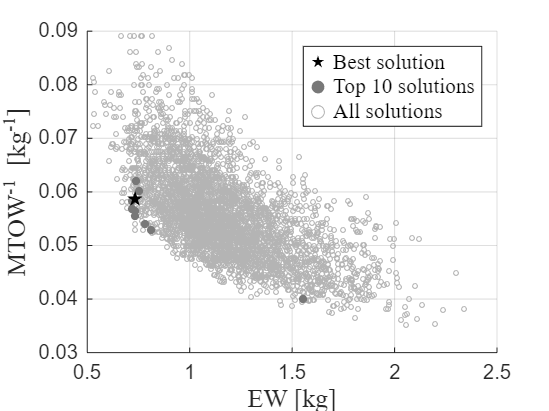

% Realiza o plot da fronteira de Pareto:
PLOT_PARETO(RESULTS);

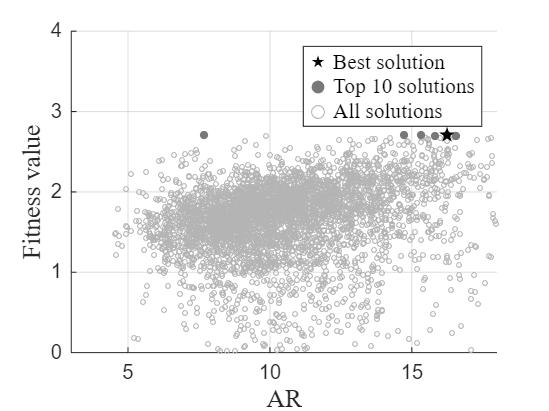


% Realiza o plot do fitness x Alongamento:
PLOT_AR(RESULTS);

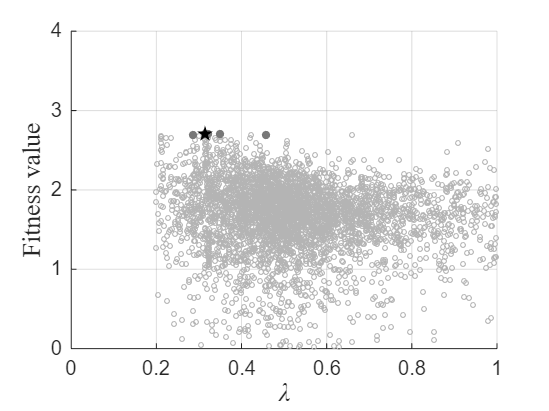


% Realiza o plot do fitness x Afilamento:
PLOT_TAPER(RESULTS);

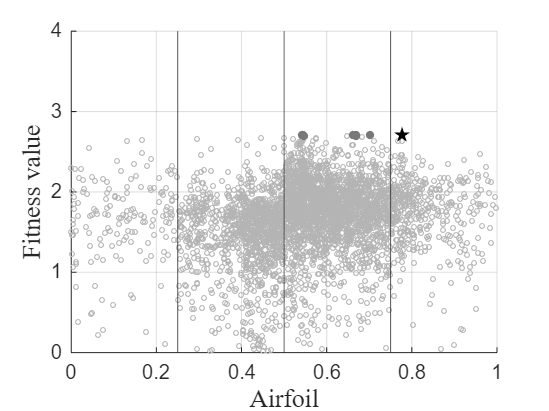


% Realiza o plot do fitness x Aerofólio:
PLOT_AIRFOIL(RESULTS);

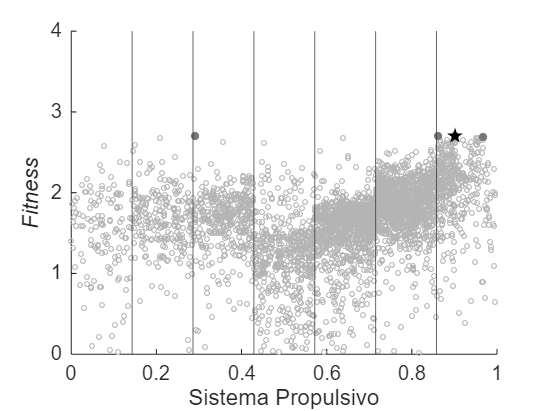


% Realiza o plot do fitness x GMP:
PLOT_GMP(RESULTS);

### **Melhor Solução**

fprintf('Corda na Raíz: %f',RESULTS.final_solution(1,1));

Corda na Raíz: 0.203809

fprintf('Razão de Afilamento: %f',RESULTS.final_solution(1,2));

Razão de Afilamento: 0.317742

fprintf('Envergadura: %f',RESULTS.final_solution(1,3));

Envergadura: 2.811379

fprintf('Posição de Afilamento: %f',RESULTS.final_solution(1,4));

Posição de Afilamento: 0.577991

fprintf('Offset na Ponta: %f',RESULTS.final_solution(1,5));

Offset na Ponta: 0.027565

fprintf('Torçao Intermediária: %f',RESULTS.final_solution(1,6));

Torçao Intermediária: 0.175699

fprintf('Torção na Ponta: %f',RESULTS.final_solution(1,7));

Torção na Ponta: 0.254474

fprintf('Aerofólio: %f',RESULTS.final_solution(1,8));

Aerofólio: 0.147042

fprintf('GMP: %f',RESULTS.final_solution(1,9));

GMP: 0.875928

fprintf('MTOW: %f',RESULTS.final_solution(1,11));

MTOW: 9.900000

fprintf('Peso Vazio: %f',RESULTS.final_solution(1,13));

Peso Vazio: 0.735748

fprintf('Área em Planta: %f',RESULTS.final_solution(1,14));

Área em Planta: 0.490499

Alongamento: 16.113917

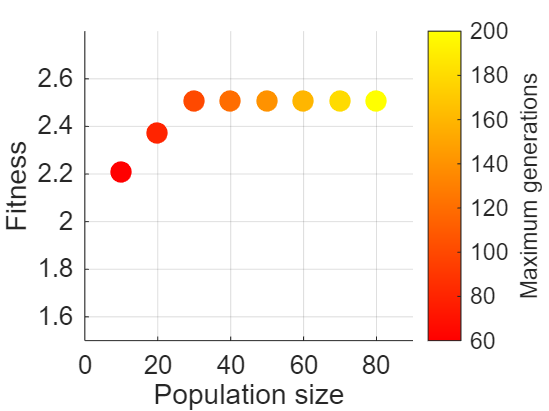

fprintf('Alongamento: %f',RESULTS.final_solution(1,15));